# Analyzing Hurricane Harvey

This script analyzes the effects of Hurricane Harvey in the US; particularly the two states which were most affected. It has been divided into four section: Background, Visualization, Analysis and Conclusion. The background deals with importing the dataset we have and finding out the states which were most impacted by  this storm. The visualization section has a few plots to understand the kind of events that we are dealing with, and their locations in the two states. Next, we analyze each state by grouping it into counties and counting the total number of events in each county, along with finding out which counties in each state had recorded the highest property damage cost. Finally, we summarize our findings and make a suggestion regarding the counties to be prioritized.

## Background and Scope

### Importing the Data

We import the file with the necessary variables; while discarding columns not needed for this analysis.

Storms_2017 = importfile("StormEvents_2017_finalProject.csv");
Storms_2017 = Storms_2017(2:end,:)

Storms_2017 = 57005×13 table
        State         Year     Month            Event_Type                               CZ_Name                           Begin_Date_Time         End_Date_Time       Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ______________    ____    _______    ________________________    ________________________________________________    ___________________    ___________________    _____________    _________    _________    _________    _______    _______

    NEW JERSEY        2017    April      Thu

Now, as given to us in the assignment introduction, we are going to focus on states that were most affected by Harvey: **Arkansas, Kentucky, Louisiana, Mississippi, North Carolina, Tennessee, and Texas. **We will also narrow our dates between August 17 and September 3rd, so as to focus solely on Harvey-related storms.

Harvey = Storms_2017(ismember(Storms_2017.State,{'ARKANSAS','KENTUCKY','LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS'}),:);
Harvey = Harvey((Harvey.Begin_Date_Time >= '17-Aug-2017') & (Harvey.End_Date_Time <= '03-Sep-2017'),:);

### Two States Most Impacted by Harvey

We wish to find the two states most affected by Hurricane Harvey in terms of Property Cost. We will do so by grouping the table by State and then sorting the column 'Property_Cost' of the table.

property_cost_by_state = grpstats(Harvey, {'State'},'sum',"DataVars",'Property_Cost')

property_cost_by_state = 7×3 table
                          State         GroupCount    sum_Property_Cost
                      ______________    __________    _________________

    ARKANSAS          ARKANSAS              52                61000    
    KENTUCKY          KENTUCKY              20             4.35e+05    
    LOUISIANA         LOUISIANA             85           7.5277e+07    
    MISSISSIPPI       MISSISSIPPI           39             9.15e+05    
    NORTH CAROLINA    NORTH CAROLINA        59           1.2338e+07    
    TENNESSEE         TENNESSEE             46             5.04e+05    
    TEXAS             TEXAS                271           7.7427e+10    


property_cost_by_state = sortrows(property_cost_by_state,'sum_Property_Cost','descend');
max_two_states = property_cost_by_state.State(1:2)

max_two_states = 2×1 categorical array
     TEXAS 
     LOUISIANA 


So, from this, we have our findings that the two states most affected in property by the storm Harvey are **Texas and Louisiana.**

### Table of Events for Two Most Impacted States

Now, we will make a table of the events of Harvey just for these states to be able to study them in more detail.

Texas_and_Louisiana = Harvey(ismember(Harvey.State,{'TEXAS','LOUISIANA'}),:)

Texas_and_Louisiana = 356×13 table
    State    Year    Month        Event_Type          CZ_Name        Begin_Date_Time         End_Date_Time       Property_Cost    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    _____    ____    ______    _________________    ___________    ___________________    ___________________    _____________    _________    _________    _________    _______    _______

    TEXAS    2017    August    Tropical Storm       MONTGOMERY     2017-08-25 12:00:00    2017-08-30 00:00:00         7e+09          NaN          

## Visualizations

### Figure of Event Types

First we want to understand and get a sense of what kind of events we are dealing with. So, we will make a histogram of the event types in the two states.

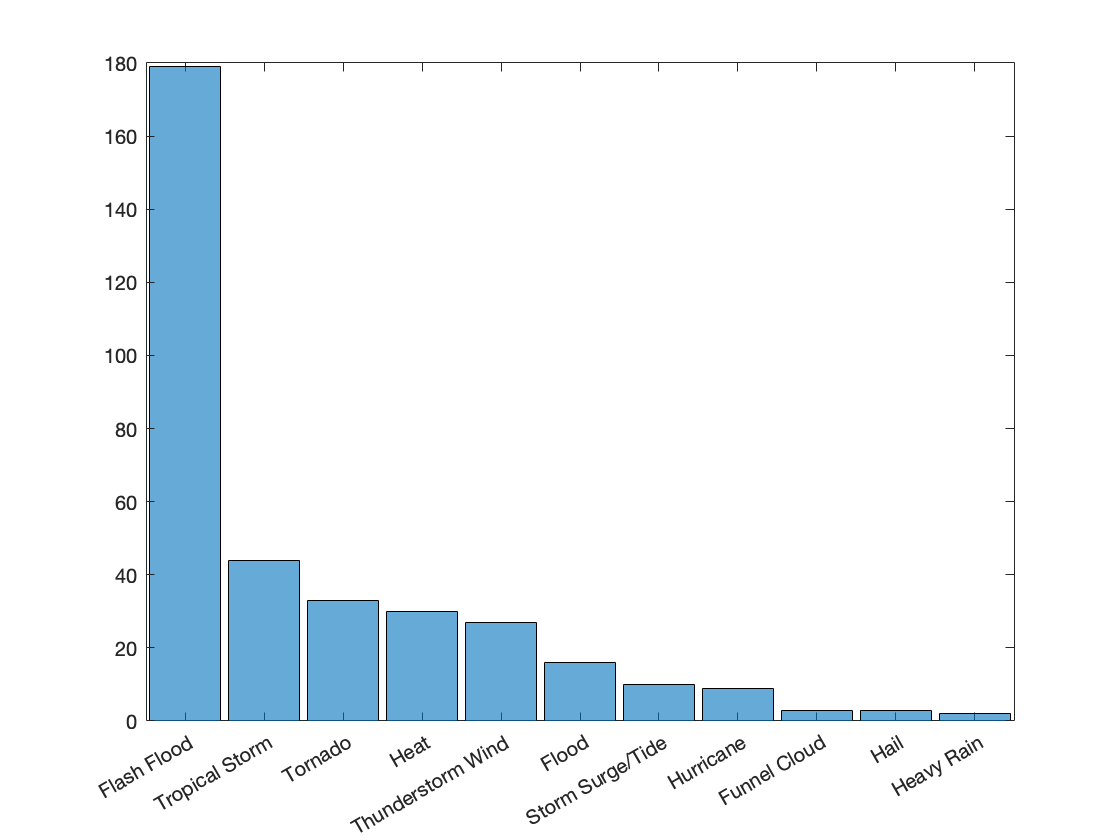

h = histogram(Texas_and_Louisiana.Event_Type,"DisplayOrder",'descend','NumDisplayBins',11);

Clearly, Flash Floods are the most common storm occurrences due to Hurricane Harvey in Texas and Louisiana.

### Figure of Event Locations

We will plot the locations of the storms in Texas and Louisiana, and we will mark them with different colours to differentiate between the two.

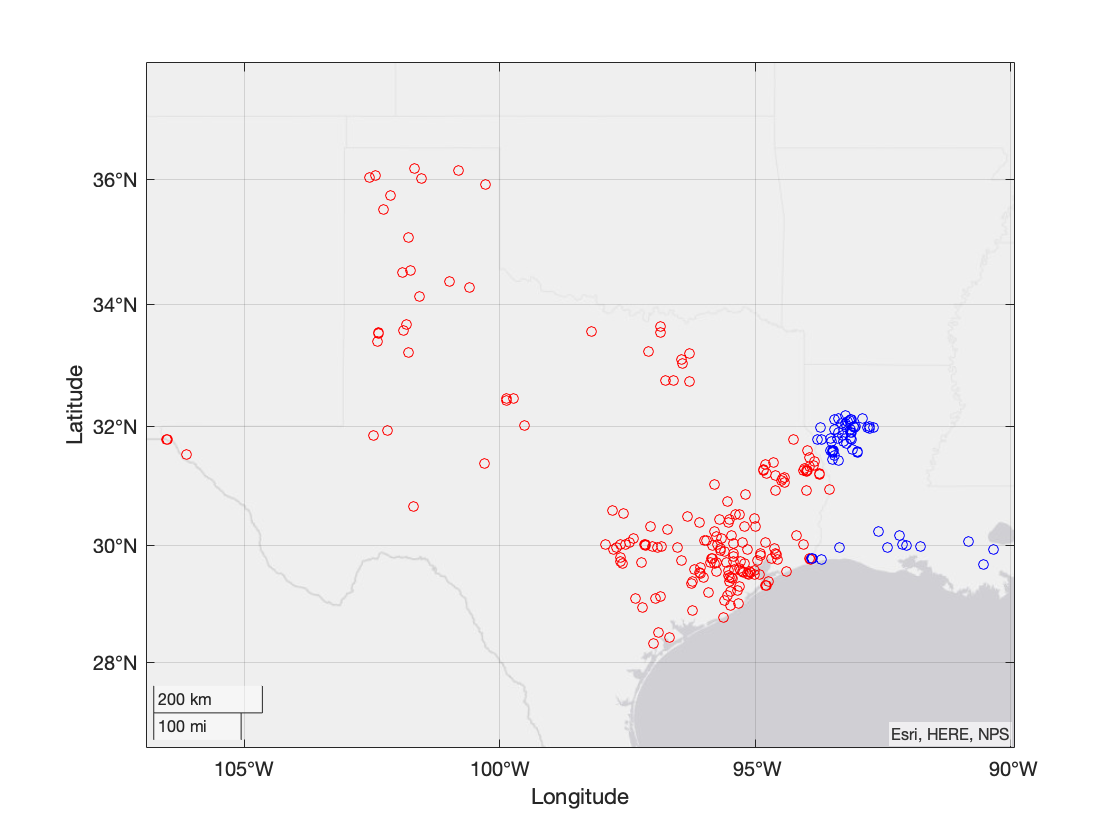

Texas = Texas_and_Louisiana(Texas_and_Louisiana.State == 'TEXAS', :);
Louisiana = Texas_and_Louisiana(Texas_and_Louisiana.State == 'LOUISIANA',:);

geoscatter(Texas.Begin_Lat, Texas.Begin_Lon, 25, "red")
hold on
geoscatter(Louisiana.Begin_Lat, Louisiana.Begin_Lon, 25, "blue")
hold off

## Analysis

### Three Counties with Most Events in Texas

Let us analyze the event distribution in Texas by counties, and identify the three counties with most events in Texas.

counties_texas = groupcounts(Texas, 'CZ_Name');
counties_texas = sortrows(counties_texas, 'GroupCount', 'descend');
max_three_counties_texas = counties_texas.CZ_Name(1:3)

max_three_counties_texas = 3×1 categorical array
     HARRIS 
     GALVESTON 
     FORT BEND 


Hence, we have the names of the counties which had the most events in Texas.

### Three Counties with Most Events in Lousiana

We apply the same procedure to the state of Louisiana.

counties_ls = groupcounts(Louisiana, 'CZ_Name');
counties_ls = sortrows(counties_ls, 'GroupCount', 'descend');
max_three_counties_ls = counties_ls.CZ_Name(1:3)

max_three_counties_ls = 3×1 categorical array
     NATCHITOCHES 
     SABINE 
     RED RIVER 


### Three Counties with Highest Property Cost in Texas

Now, we find out the three counties that reported the highest property costs in Texas.

counties_by_cost_tx = grpstats(Texas, "CZ_Name","sum","DataVars","Property_Cost");
counties_by_cost_tx = sortrows(counties_by_cost_tx, "sum_Property_Cost","descend");
max_three_cost_tx = counties_by_cost_tx(1:3, [1 3])

max_three_cost_tx = 3×2 table
                   CZ_Name      sum_Property_Cost
                  __________    _________________

    GALVESTON     GALVESTON             2e+10    
    FORT BEND     FORT BEND        1.6004e+10    
    MONTGOMERY    MONTGOMERY          1.4e+10    


### Three Counties with Highest Property Cost in Louisiana

We do the same for Louisiana.

counties_by_cost_ls = grpstats(Louisiana, "CZ_Name","sum","DataVars","Property_Cost");
counties_by_cost_ls = sortrows(counties_by_cost_ls, "sum_Property_Cost","descend");
max_three_cost_ls = counties_by_cost_ls(1:3, [1 3])

max_three_cost_ls = 3×2 table
                   CZ_Name      sum_Property_Cost
                  __________    _________________

    CALCASIEU     CALCASIEU            6e+07     
    BEAUREGARD    BEAUREGARD         1.5e+07     
    ACADIA        ACADIA               2e+05     


## Conclusions and Recommendations

Notice that we narrowed down the dataset to two of the most impacted states. Within the states, we identified the counties with the most events and those with the highest amounts of property costs. As can be seen, in Texas, the  property costs are much higher than those in Louisiana, by several orders of magnitude. So, I would recommend the company to send its people to these counties first, followed by some others from Texas which have a very high property cost. I would prioritize the counties of Louisiana after the most damaged ones in Texas.